assert(isfile("DCS_2D_Disk.mlx"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 20; % number of elements in z direction

## Uniform Grid

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 5;
Sensor.side_length = 0.8e-3;

Sensor.position = [linspace(0,30e-3,Sensor.num); 2.5e-3*ones(1,Sensor.num)];

#### Model

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildDiskModel(r,z);

calculate geometry took 0.01 seconds


clear r z

Model.conductivity = 3.774e7 * ones(1,Model.num_elms); % (S/m)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 30.39 seconds


#### Solve in frequency domain

EM.frequency_domain.current = 1; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
EM.frequency_domain.angular_frequency = 2*pi*5000; % (rad/s)

[Model, EM, Sensor] = SolveFrequency2D(GoverningEquation, Model, EM, Sensor);

solve J took 0.01 seconds
solve B_E took 0.91 seconds
solve B_C took 0.91 seconds


#### Plot result

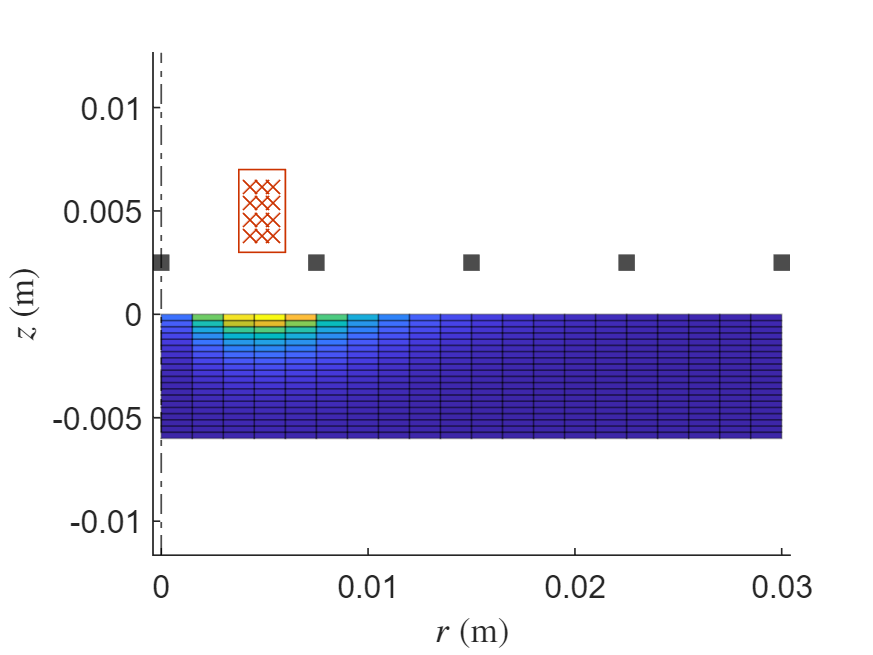

PlotWorld2D(Model, EM, Sensor, abs(Model.frequency_domain.J));

% colormap gray

## Adaptive Grid

#### Model

pdf = reshape(abs(Model.frequency_domain.J).^-0.5, [disk.n_r, disk.n_z]);
r_cdf = cumsum(pdf(:,end))';  r_cdf = [0 r_cdf] / r_cdf(end);
z_cdf = cumsum(pdf(6,:));     z_cdf = [0 z_cdf] / z_cdf(end);

r = disk.radius * r_cdf;
z = disk.height * z_cdf - disk.height;

Model2 = BuildDiskModel(r,z);

calculate geometry took 0.00 seconds


clear pdf r_cdf z_cdf r z

#### Plot adaptive grid

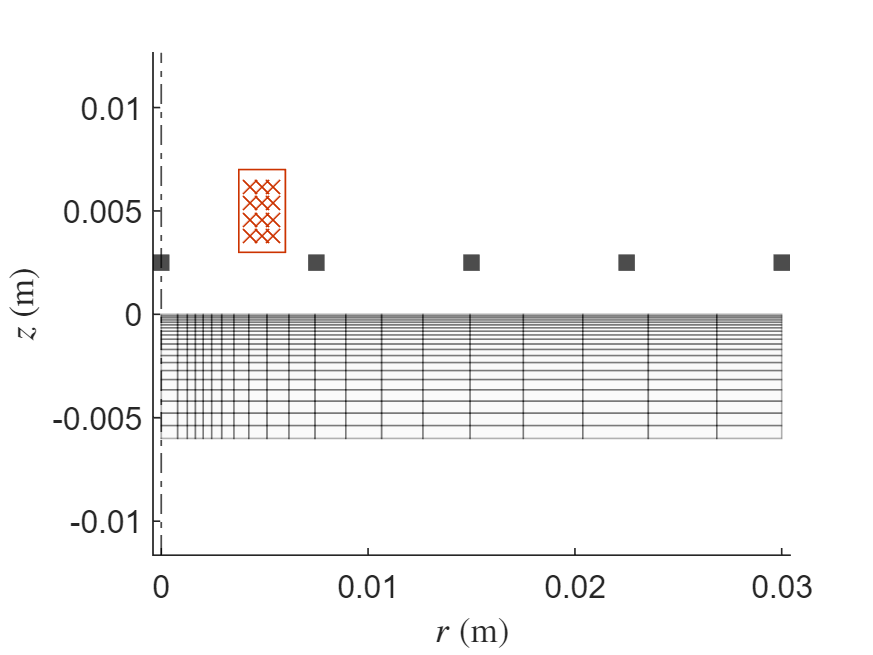

clf;
PlotWorld2D(Model2, EM, Sensor);

## Compare with FEA

data = readmatrix('FEA_data/J.csv', 'CommentStyle','%');
FEA.r = reshape(data(:,1), 200, []);
FEA.z = reshape(data(:,2), 200, []);
FEA.J = reshape(data(:,3), 200, []);
clear data

#### Plot

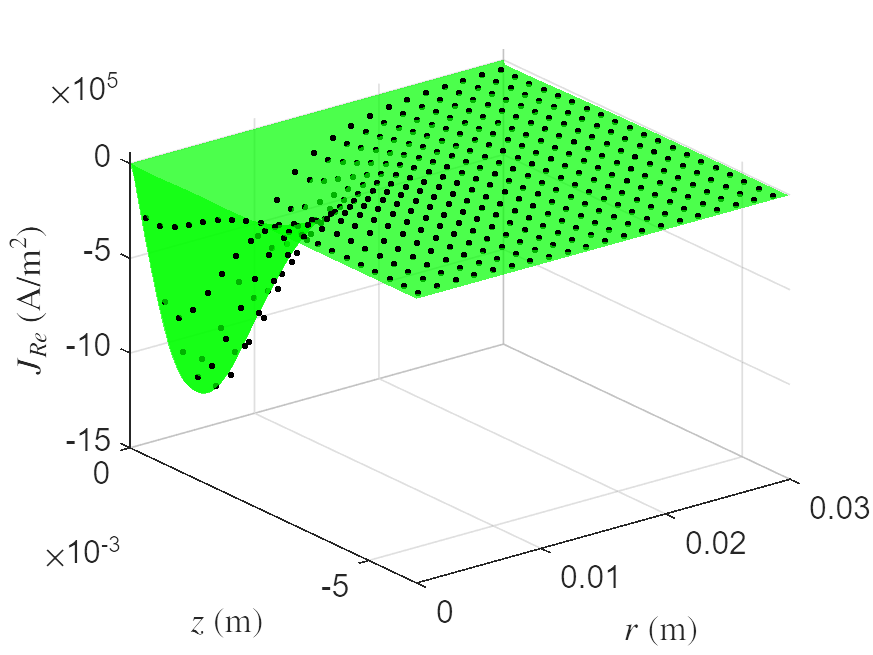

clf
surf(FEA.r,FEA.z, real(FEA.J), 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), real(Model.frequency_domain.J), 'k.')
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Re}$ (A/m$^2$)", 'Interpreter','latex')
hold off

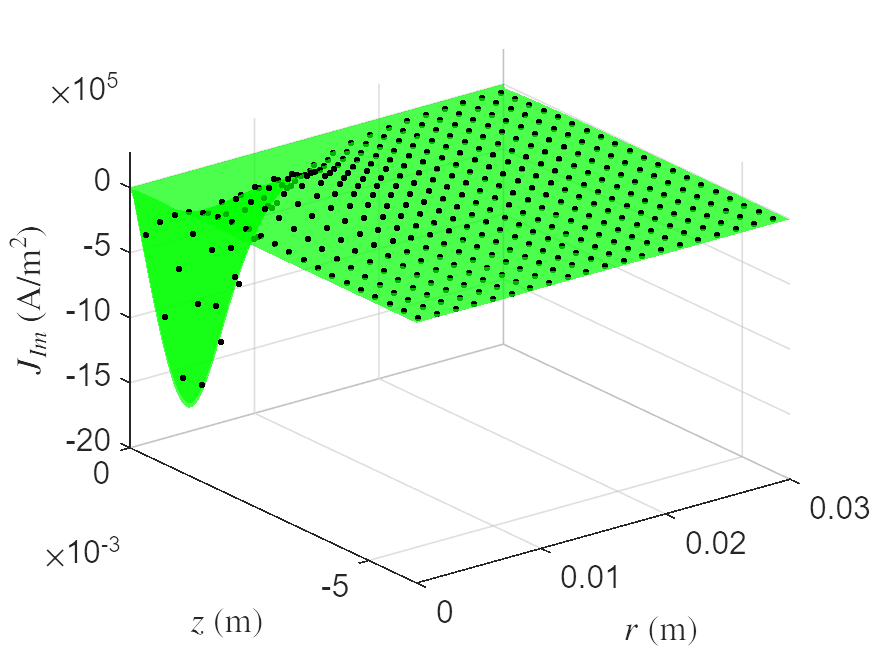


clf 
surf(FEA.r,FEA.z, imag(FEA.J), 'FaceColor','g', 'FaceAlpha',0.7, 'LineStyle','none')
hold on
plot3(Model.elms_center(1,:), Model.elms_center(2,:), imag(Model.frequency_domain.J), 'k.')
xlabel("$r$ (m)", 'Interpreter','latex')
ylabel("$z$ (m)", 'Interpreter','latex')
zlabel("$J_{Im}$ (A/m$^2$)", 'Interpreter','latex')
hold off